clc, clear, close all

a = 0;
b = 10;
x0 = 1;


## --- Eulerova metóda ---

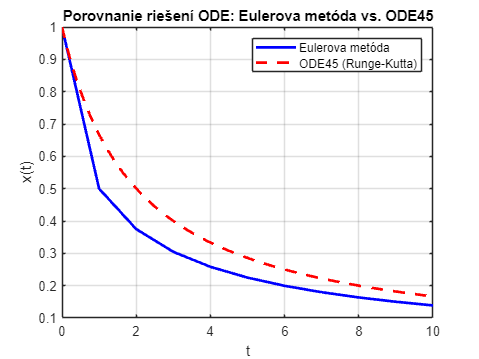


h1 = 1; % krok
t1 = a:h1:b;
n1 = length(t1);

x1 = zeros(1,n1);
x1(1) = x0;

for i = 1:n1-1
    a1 = odeFcn1D(t1(i), x1(i));
    x1(i+1) = x1(i) + h1*a1;
end

[t2, x2] = ode45(@odeFcn1D, [a b], x0);

plot(t1, x1, 'b-', 'LineWidth', 2); hold on
plot(t2, x2, 'r--', 'LineWidth', 2);
grid on
xlabel('t')
ylabel('x(t)')
title('Porovnanie riešení ODE: Eulerova metóda vs. ODE45')
legend('Eulerova metóda', 'ODE45 (Runge-Kutta)')

## --- Lichobežníková metóda ---

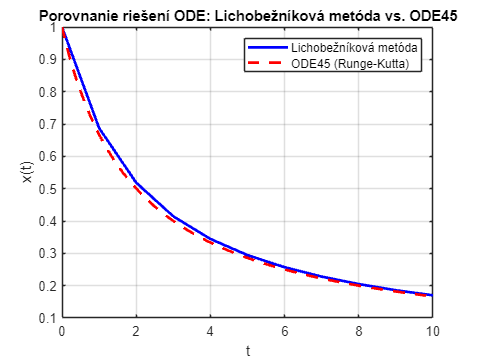


clc, clear, close all

a = 0;
b = 10;
x0 = 1;

h1 = 1;
t1 = a:h1:b;
n1 = length(t1);

x1 = zeros(1,n1);
x1(1) = x0;

for i = 1:n1-1
    a1 = odeFcn1D(t1(i), x1(i));
    a2 = odeFcn1D(t1(i)+h1, x1(i)+h1*a1);
    x1(i+1) = x1(i) + (h1/2)*(a1 + a2);
end

[t2, x2] = ode45(@odeFcn1D, [a b], x0);

plot(t1, x1, 'b-', 'LineWidth', 2); hold on
plot(t2, x2, 'r--', 'LineWidth', 2);
grid on
xlabel('t')
ylabel('x(t)')
title('Porovnanie riešení ODE: Lichobežníková metóda vs. ODE45')
legend('Lichobežníková metóda', 'ODE45 (Runge-Kutta)')

## --- Runge-Kutta 4. rádu ---

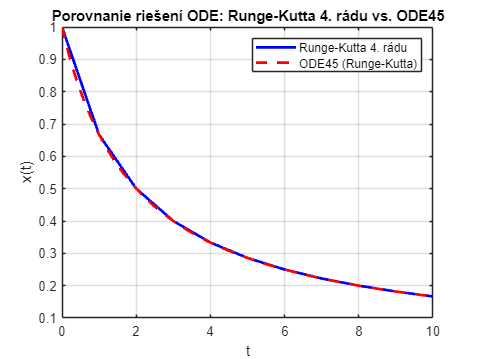


clc, clear, close all

a = 0;
b = 10;
x0 = 1;

h1 = 1;
t1 = a:h1:b;
n1 = length(t1);

x1 = zeros(1,n1);
x1(1) = x0;

for i = 1:n1-1
    a1 = odeFcn1D(t1(i), x1(i));
    a2 = odeFcn1D(t1(i) + h1/2, x1(i) + (h1/2)*a1);
    a3 = odeFcn1D(t1(i) + h1/2, x1(i) + (h1/2)*a2);
    a4 = odeFcn1D(t1(i) + h1, x1(i) + h1*a3);
    x1(i+1) = x1(i) + (h1/6)*(a1 + 2*a2 + 2*a3 + a4);
end

[t2, x2] = ode45(@odeFcn1D, [a b], x0);

plot(t1, x1, 'b-', 'LineWidth', 2); hold on
plot(t2, x2, 'r--', 'LineWidth', 2);
grid on
xlabel('t')
ylabel('x(t)')
title('Porovnanie riešení ODE: Runge-Kutta 4. rádu vs. ODE45')
legend('Runge-Kutta 4. rádu', 'ODE45 (Runge-Kutta)')